**Find the area of black rectangle (include thickness of boarder in area calculations)**

**Also find the coordinates of the four corners**

Read image

img = imread('blackRectangle.png')

img = 50×50×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   

Show image

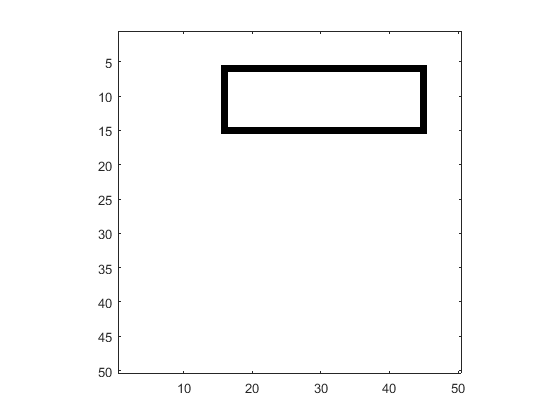

image(img)
axis tight; axis equal;

Create a mask to indicate the black pixels in the image

mask2d = img(:,:,1)==0 & img(:,:,2)==0 & img(:,:,3)==0

mask2d = 50×50 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

Find the coordinates (rows,cols) of the located black pixels

[rows, cols] = find(mask2d)

rows =      6
     7
     8
     9
    10
    11
    12
    13
    14
    15


cols =     16
    16
    16
    16
    16
    16
    16
    16
    16
    16


Use max and min to determine the top-to-bottom and left-to-right bounds of the black pixels in the image and subtract to determine the height and width of the area covered by the black boardered rectangle

- Note as in the homework: Be sure to include� both� the first and last row or column when calculating dimensions. In other words, if the leftmost red pixel is in column 4 and the rightmost red pixel is in column 8, then the width of the bar is 5 pixels. 


height = max(rows)-min(rows)+1

height = 10

width = max(cols)-min(cols)+1

width = 30

Calculate area

area = width * height

area = 300

Locate Corners

topLeft = [min(rows), min(cols)]

topLeft =      6    16


topRight = [min(rows), max(cols)]

topRight =      6    45


bottomLeft = [max(rows), min(cols)]

bottomLeft =     15    16


bottomRight = [max(rows), max(cols)]

bottomRight =     15    45
